Parameters

fc = 2000; %2kHz

Text Encoding

text = ['hello world, vicky was in the musical. ' ...
    'Yichen does not wear glasses' ...
    'Yichen smushed matlab' ...
    'turns out implementation is hard' ...
    'Vicky is happy she is a software engineering'...
    'Yichen is suprised by Vickys career choise'];
text_bin = dec2bin(double(text));
s = size(text_bin);
bin_str = reshape(text_bin.'-'0',1,[]);
% a = [];
% for c=1:length(bin_str)
%     append(a, str2double(bin_str(c)));
% end

Pulse Shaping

%pulse = (sqrt(2)*cos(2*pi*fc*time)).* bin_str;

Transmit

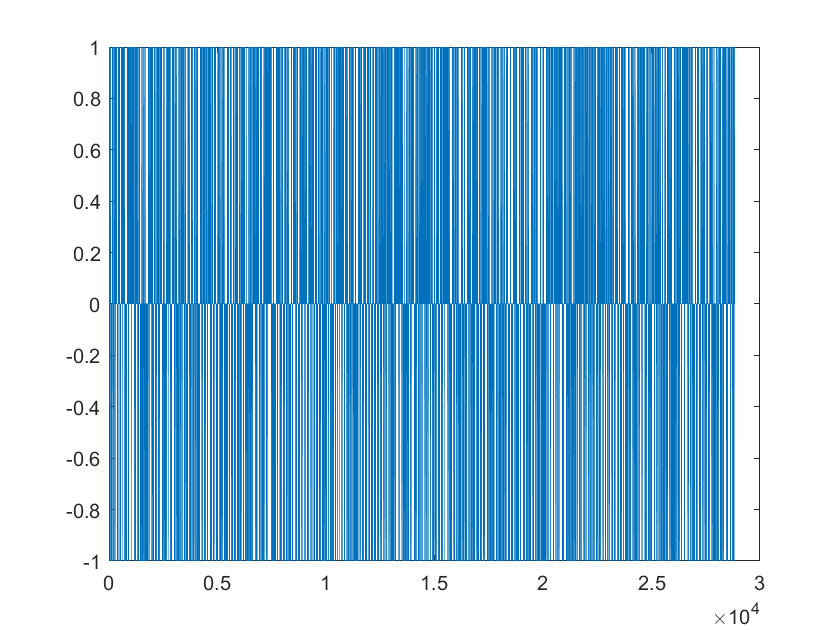

bin_str = 2 * bin_str - 1;
bin_str_us = upsample(bin_str, 20);
plot(bin_str_us);

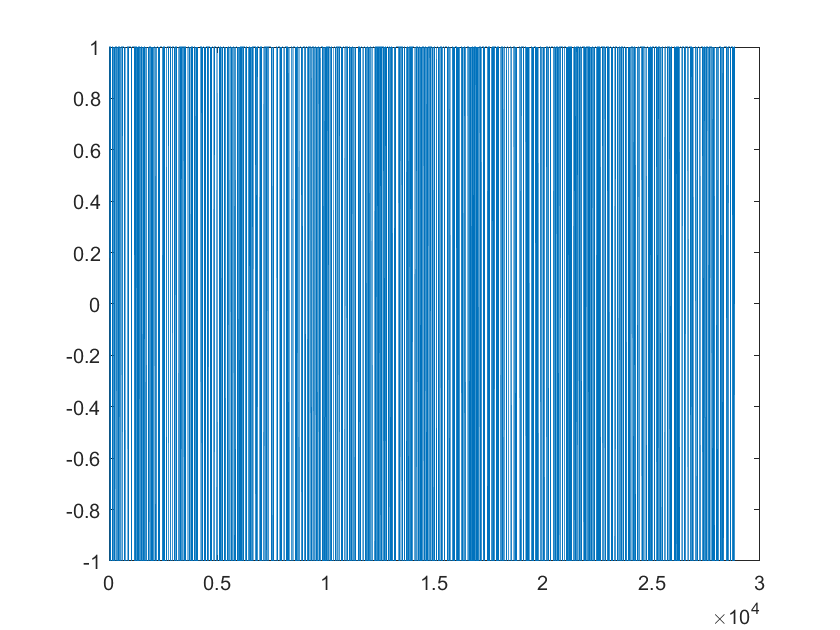

pulse = ones(20, 1);
X_I = conv(bin_str_us, pulse);
plot(X_I);

time = linspace(0,1,length(X_I));  %update to the length of the binary string
X = X_I .* cos(2*pi*fc*time) % then play this on the computer with sound

X =     1.0000    0.9067    0.6441    0.2614   -0.1702   -0.5700   -0.8634   -0.9956   -0.9421   -0.7127   -0.3502    0.0775    0.4909    0.8126    0.9826    0.9692    0.7750    0.4361    0.0158   -0.4075   -0.7547   -0.9610   -0.9880   -0.8306   -0.5181   -0.1090    0.3205    0.6902    0.9310    0.9981    0.8789    0.5956    0.2012   -0.2308   -0.6197   -0.8929   -0.9995   -0.9195   -0.6680   -0.2917   -0.1390   -0.5438   -0.8470   -0.9922   -0.9522   -0.7345   -0.3796    0.0460    0.4631    0.7938


%n = randn(1000,1);
sound(X);